# 案例：曲线渐变色、填充渐变色

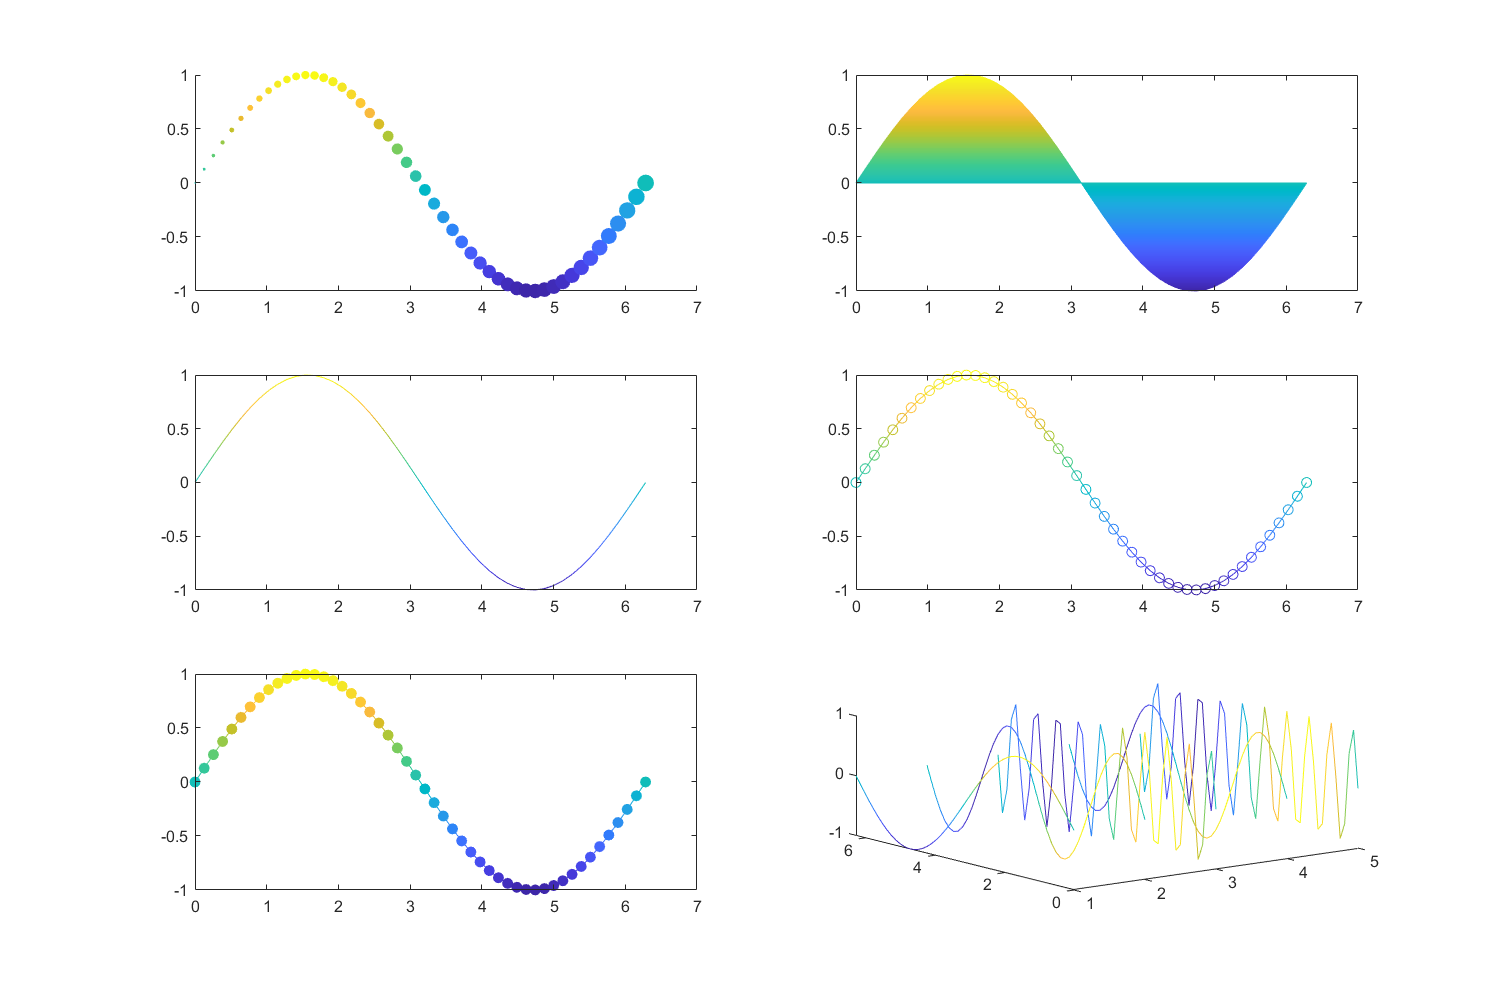

clear;clc;
x = linspace(0, 2*pi, 50);
y = sin(x);
sizeMarker = linspace(1, 100, length(x));
colorMarker = y;
figure("Position", [0, 0, 1200, 800])
subplot(3, 2, 1)
scatter(x, y, sizeMarker, colorMarker, 'o', 'filled')
subplot(3, 2, 2)
fill(x, y, colorMarker, 'EdgeColor', 'interp')
subplot(3, 2, 3)
fill([x, NaN], [y, NaN], [colorMarker, NaN], 'EdgeColor', 'interp')
subplot(3, 2, 4)
fill([x, NaN], [y, NaN], [colorMarker, NaN], 'Marker', 'o', 'EdgeColor', 'interp')
subplot(3, 2, 5)
fill([x, NaN], [y, NaN], [colorMarker, NaN], 'Marker', 'o', 'EdgeColor', 'interp', 'MarkerFaceColor','flat')
subplot(3, 2, 6)
fill3([ones(size(x)), NaN], [x, NaN], [y, NaN], [colorMarker NaN], 'EdgeColor', 'interp')
hold on
for i = 2 : 5
    if mod(i, 2) == 0
        y = sin(2*x);
        fill3([i * ones(size(x)), NaN], [x, NaN], [y, NaN], [colorMarker NaN], 'EdgeColor', 'interp')
    else
        y = sin(10*x);
        fill3([i * ones(size(x)), NaN], [x, NaN], [y, NaN], [colorMarker NaN], 'EdgeColor', 'interp')
    end
end
hold off